# Training Unit 8: Arduino - MATLAB/Simulink

Fink Lucas / Teichtmeister Marcus, 05.11.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## ENTER COM PORT OF CONNECTED ARDUINO

COM = 'COM7';

## Establish Connection Between Arduino Board and MATLAB

a = arduino(COM,'Uno','BaudRate',115200);

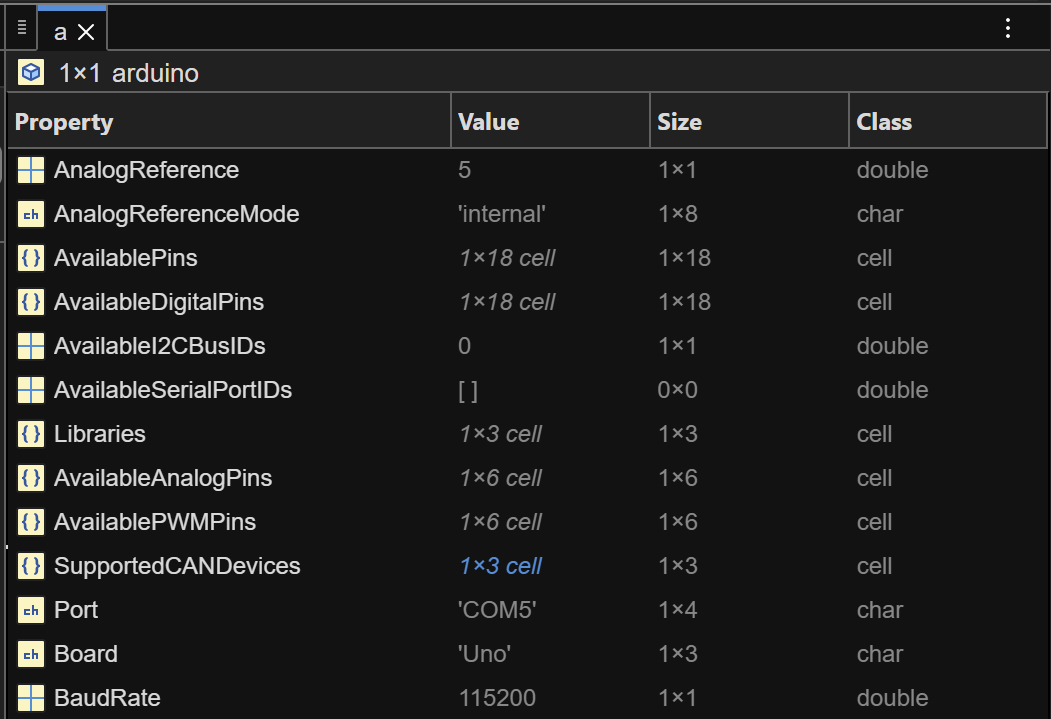

The variable `a` is the Arduino Object representing the active serial connection to the hardware. Executing methods(a) outputs a list of all available functions for controlling the board's pins and supported peripherals

methods(a)


Methods for class arduino:

addon              apds9960           canChannel         configurePin       device             motorCarrier       playTone           readDigitalPin     readVoltage        rotaryEncoder      scanI2CBus         servo              shiftRegister      ultrasonic         writeDigitalPin    writePWMDutyCycle  writePWMVoltage    

Methods of arduino inherited from handle.



## MATLAB to Control Inputs and Outputs of Board

Configuring the Pin D2 as a standard high-impendace input

- State is UNDEFINED when floating (unconnected).

configurePin(a, 'D2', 'DigitalInput')

- type as DigitalInput -> input is in an undefined state (when floatend),

- there is also difference if touching the wire by hand or not

- type as Pullup -> input has an defined state (HIGH), when floatend its

- "1", gnd its "0"

ret = readDigitalPin(a, 'D2')

ret =      0.0000e+000

It can be observed that the state is switching between 0 and 1 when calling the command several times

### Real-Time Signal Monitoring

A real-time plotting loop visualizes digital pin states dynamically, functioning as a software oscilloscope. This allows for the observation of signal stability and instantaneous value changes during the sampling period.

figure
plot(1,1); % create plot with dummy value
ax = gca; % get handle of current axes;
line = get(ax, 'Children'); % get handle to line object
for run_var = 1 : 100
 read_value = readDigitalPin(a, 'D2');
 pause(0.1);
 line.XData = [line.XData run_var];
 line.YData = [line.YData read_value];
end

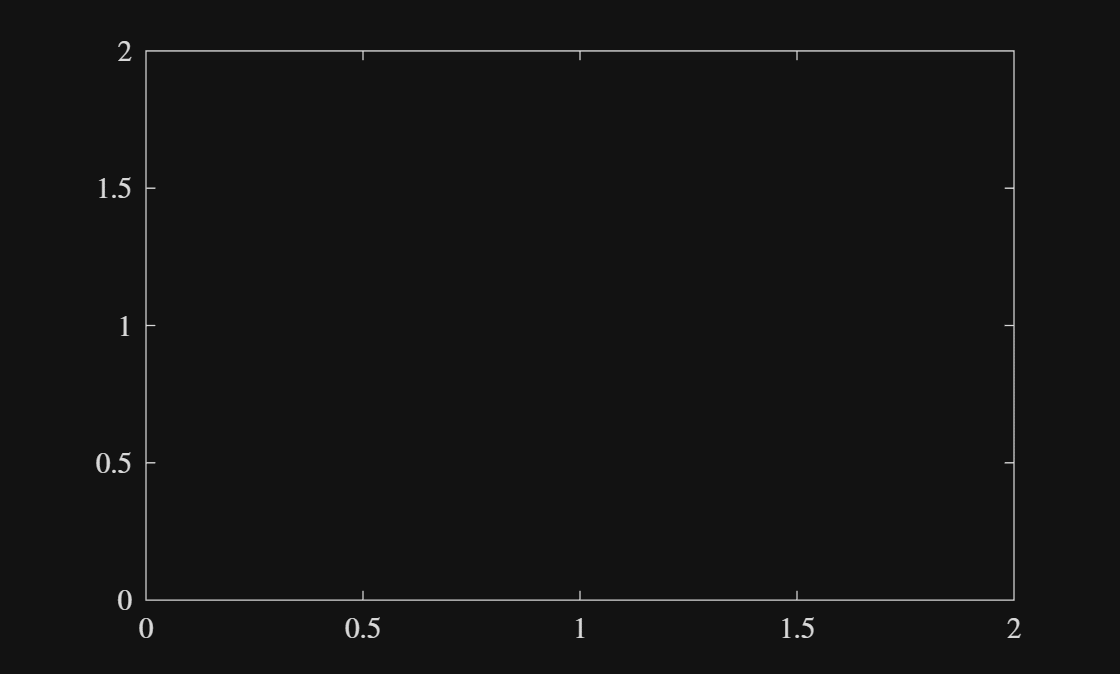

The 'Pullup' mode enables an internal resistor to force a defined logic HIGH state when the circuit is open. This stabilizes the reading by eliminating noise, ensuring the pin reads LOW only when grounded.

configurePin(a, 'D4', 'Pullup')
configurePin(a, 'D3', 'DigitalOutput')

A physical loopback connection between the output and input pins is utilized to validate signal transmission. 

writeDigitalPin(a, 'D3', 1);
readDigitalPin(a, 'D4')

ans =      1.0000e+000

## Finding the Minimum Cycle Time

The testbench evaluates the communication latency between MATLAB and the Arduino Board (Cycle Time). The execution time for a 'writeDigitalPin' command is measured across varying Baud rates to determine the minimum possible latency.

% Initializes connection at standard speed (115200 baud) and records execution times
clearvars -except COM
a = arduino(COM,'Uno','BaudRate', 115200);

configurePin(a, 'D13', 'DigitalOutput')
time115k = zeros(1, 100);
for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time115k(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

% Re-initializes connection at low speed (110 Baud) to observe increased latency
clear a
a = arduino(COM,'Uno','BaudRate', 110);

Updating server code on board Uno (COM7). This may take a few minutes.



configurePin(a, 'D13', 'DigitalOutput')
time110 = zeros(1, 100);
for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time110(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

% Re-initializes connection at high speed (256000 Baud) to find the minimum cycle time.
clear a
a = arduino(COM,'Uno','BaudRate', 256000);

Updating server code on board Uno (COM7). This may take a few minutes.



configurePin(a, 'D13', 'DigitalOutput')
time256k = zeros(1, 100);
for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time256k(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

**Analysis & Visualization**

Plots the recorded time stamps to visualize the distribution of cycle times

figure('Name', 'Cycle Time Analysis');
clf;
values = ones(1,100); 
hold on;
h1 = stem(time115k, values, 'Color', 'b', 'LineWidth', 1.5);
h2 = stem(time110, values, 'Color', 'r', 'LineWidth', 1.5);
h3 = stem(time256k, values, 'Color', '#EDB120', 'LineWidth', 1.5); % Yellow/Gold
hold off;

title('Impact of Baud Rate on Arduino Command Latency');
xlabel('Cycle Time / Execution Latency in s');
ylabel('Samples in 1');
legend([h1(1), h2(1), h3(1)], ...
    {'115200 Baud (Standard)', '110 Baud (Slow)', '256000 Baud (Fast)'}, ...
    'Location', 'north');
grid on;

- The plot demonstrates that the cycle time is inversely proportional to the Baud rate, where higher communication speeds result in significantly reduced execution latency. Specifically, the 256000 Baud configuration achieves the minimum cycle time, while the 110 Baud setting introduces substantial delay.

mintime115k = min(time115k)

mintime115k =     12.6549e-003

mintime110 = min(time110)

mintime110 =    214.7664e-003

mintime256k = min(time256k)

mintime256k =     17.0476e-003

## Creating a Visual Binary Counter

Initializes the connection and configures 4 LEDs for binary display.

clearvars -except COM
a = arduino(COM,'Uno','BaudRate', 115200);

Updating server code on board Uno (COM7). This may take a few minutes.


configurePin(a, 'D8', 'DigitalOutput')
configurePin(a, 'D9', 'DigitalOutput')
configurePin(a, 'D10', 'DigitalOutput')
configurePin(a, 'D11', 'DigitalOutput')

### **Task 1: Automatic Binary Counter (0 to 15)**

Loops through numbers 0-15, converts them to 4-bit binary, and updates LEDs 

    % Loop to create a binary counter
    for i = 0:15
        % Convert counter to binary and write to output pins
        binaryValue = dec2bin(i, 4) - '0'; % Convert to binary and to numeric array
        writeDigitalPin(a, 'D8', binaryValue(1)); % Write to D8
        writeDigitalPin(a, 'D9', binaryValue(2)); % Write to D9
        writeDigitalPin(a, 'D10', binaryValue(3)); % Write to D10
        writeDigitalPin(a, 'D11', binaryValue(4)); % Write to D11
        
        pause(1); % Pause for visibility
    end


### Task 2: Interactive User Input

Continuously requests user input to set the binary display

counter = 0;

while true
    userInput = input('Enter a number (0-15) to display in binary (leave empty to exit): ', 's');
    
    if isempty(userInput) || ~isnumeric(str2double(userInput))
        disp('Exiting the counter.');
        break;
    end
    
    numValue = str2double(userInput);
    
    % Validate the input range
    if numValue >= 0 && numValue <= 15
        binaryValue = dec2bin(numValue, 4) - '0'; % Convert to binary and to numeric array
        writeDigitalPin(a, 'D8', binaryValue(1)); % Write to D8
        writeDigitalPin(a, 'D9', binaryValue(2)); % Write to D9
        writeDigitalPin(a, 'D10', binaryValue(3)); % Write to D10
        writeDigitalPin(a, 'D11', binaryValue(4)); % Write to D11
    else
        disp('Please enter a number between 0 and 15.');
    end
end

Exiting the counter.


## Using the PWM Output and the ADC Input for LED Intensity Control

onfigures Pin D5 as a PWM (Pulse Width Modulation) output to control LED intensity.

- The loop fades the LED from 0V (Off) to 5V (Max Brightness) and back to 0V

configurePin(a, 'D5', 'PWM')
writePWMVoltage(a, 'D5', 2)

for i = 1:5
    writePWMVoltage(a, 'D5', i)
    pause(1)
end
for k = 1:5
    writePWMVoltage(a, 'D5', 5-k)
    pause(1)
end

### ADC Input Analysis

Measuring PWM Output

- setting the  PWM to 2.5V (50% duty cycle) and attempt to read it with A0

configurePin(a, 'A0', 'AnalogInput') % Configures Pin A0 to measure a voltage

writePWMVoltage(a, 'D5', 2.5);
readVoltage(a, 'A0')

ans =      4.9951e+000

The read value will fluctuate between 0V and 5V. Reason: PWM is not a true analog voltage; it is a square wave switching between 0V and 5V. The ADC takes an instantaneous snapshot, capturing the signal either during a "High" pulse or a "Low" gap, rather than the average.

### Measuring Potentiometer

Connecting Potentiometer to A0

potRead = readVoltage(a, 'A0')

potRead =      2.5806e+000

This reading is stable and correct. The reason is that a potentiometer acts as a voltage divider, providing a constant DC voltage which the ADC can sample accurately.

### Integrated Intensity Control Loop

Continuously reads the Potentiometer voltage (A0) and applies it to the LED (D5)

zeroTimer = []; 

while true
    voltage = readVoltage(a, 'A0');     % 1. Read Potentiometer
    
    writePWMVoltage(a, 'D5', voltage);  % 2. Write to LED (Map Input directly to Output)
    
    if voltage < 0.1  % 3. Exit Logic (0V Detection)
        if isempty(zeroTimer)
            zeroTimer = tic; 
        elseif toc(zeroTimer) > 3
            disp('Shutdown triggered: 0V detected for >3 seconds.');
            writePWMVoltage(a, 'D5', 0); 
            break;
        end
    else
        zeroTimer = [];
    end
    pause(0.05); 
end

Shutdown triggered: 0V detected for >3 seconds.


clear

## Connecting the Arduino Hardware to Simulink

**Connection Modes and Testing**

**1) External Mode (Monitor & Tune)**

- Setup: A Digital Output block (Common library) was added and connected to a Constant block.

- Procedure: The model was configured to run in "External Mode". In this mode, Simulink generates C++ code from the model, compiles it, and deploys it to the Arduino board. The board runs the code in real-time while maintaining a data link to Simulink for parameter tuning and signal monitoring.

- Observation: This mode requires successful code generation and cross-compilation. If the COM port is busy or incorrect, the deployment fails.

**2) Inputs/Outputs Mode (Connected IO)**

- Procedure: The system was switched to "Connected IO" .

- Result: Connection was successfully established without full code generation. Changing the Constant block value from `0` to `1` instantly toggled the physical output (LED) on the board.

### Controlling an output with an input from the Arduino Uno

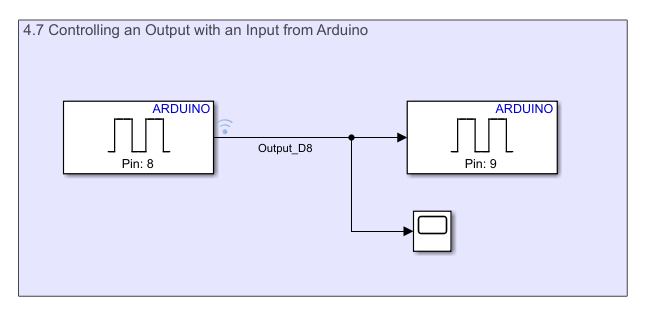

** Experimental Observations:**

**1) Floating Input (Open Connection)**

- **Observation:** When the input wire is left unconnected (neither 5V nor GND), the LED flickers or blinks randomly. The Scope trace shows erratic switching between 0 and 1.

- **Explanation:** The Arduino digital pin is in a **High Impedance state** (floating). This noise is interpreted as random logic levels, similar to the behavior observed in Task 4.2 before activating the internal pull-up resistor. 

**2) Driven Input (Defined States)**

- **Logic High:** Connecting the input wire to **5V** results in a stable `1` on the Scope and the LED turns **ON**.

- **Logic Low:** Connecting the input wire to **GND** results in a stable `0` on the Scope and the LED turns **OFF**.

**3) Signal Visualization**

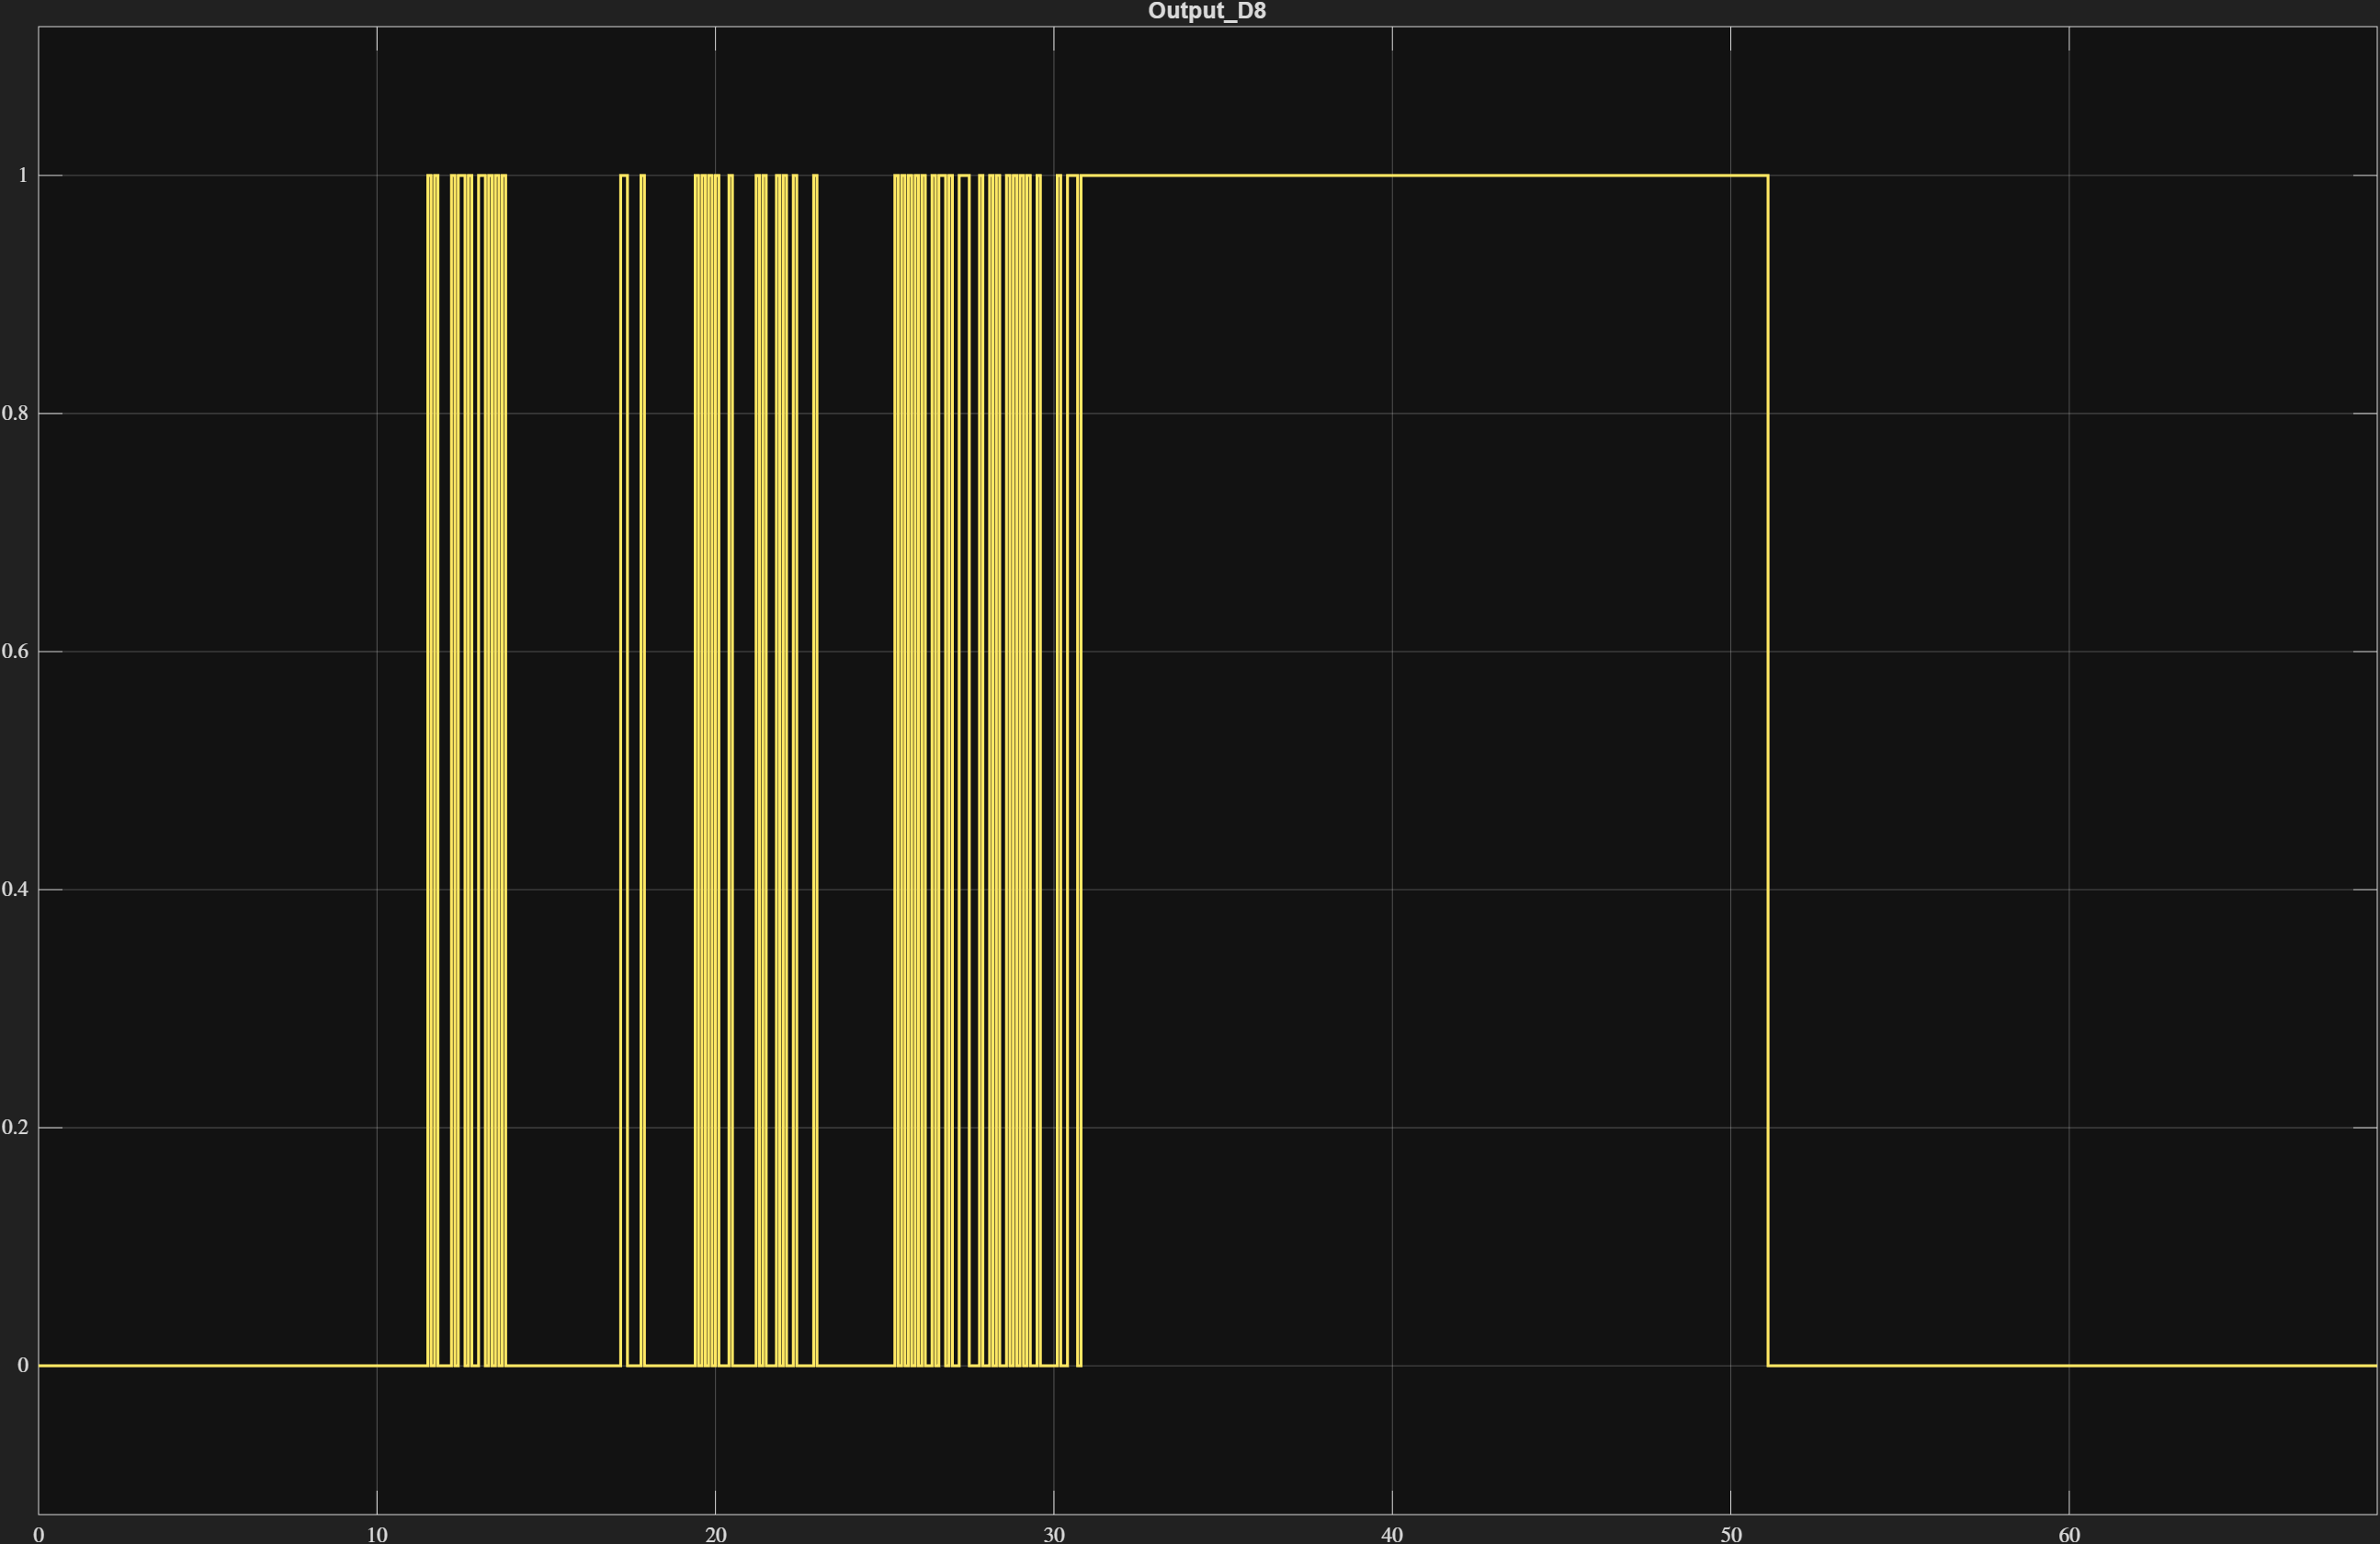

### **Controlling LED Intensity with a potentiometer**

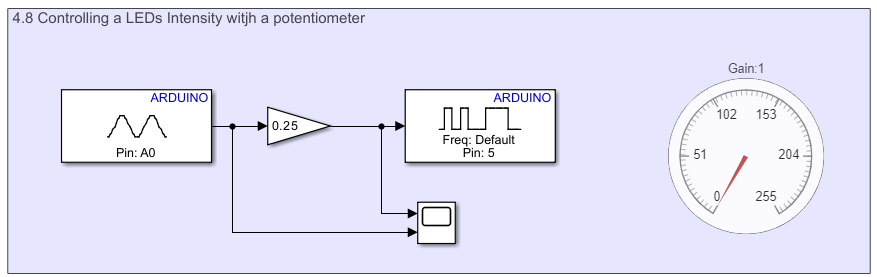

**Input Characterization**

- **Result (Analog Input):** The block outputs a 10-bit integer value ranging from **0 to 1023**.

- 0 = 0V (GND)

- 1023 = 5V (Reference Voltage)

**PWM Output Characterization**

- **Result (Data Format):** The block expects an 8-bit integer value ranging from **0 to 255**.

- 0 = 0% Duty Cycle (LED Off)

- 127 = ~50% Duty Cycle (Medium Brightness)

- 255 = 100% Duty Cycle (Max Brightness)

**Signal Integration and Scaling**

Direct connection is not possible because the Input range (0-1023) exceeds the Output range (0-255). Connecting them directly would cause the LED to reach maximum brightness at only 25% of the potentiometer's rotation (value 255).

Solution: A scaling factor is required to map the 10-bit input to the 8-bit output.

### Checking the Minimal Cycle Time in the Simulink Model

**Minimum Cycle Time Analysis (Connected IO Mode)**

**Results & Observations:**

- **Parameter Acceptance:** Simulink accepted the 0.0001 s step size and smaller ones without an error; the simulation executed successfully.

- **Time Dilation (Slow Motion):** While the simulation ran, it lost **Real-Time synchronization**. The simulation clock advanced significantly slower than the Real World Time.

- The physical round-trip communication via USB takes to long at some point.

- Since the requested step is smaller than the physical communication latency (~4 ms), Simulink pauses after every step to wait for the hardware.

Conclusion:

In "Inputs/Outputs" mode, the limiting factor is not the processing speed of the Arduino or the PC, but the Serial Communication Latency (Baud Rate & USB Overhead). While the solver allows for microsecond precision settings, the hardware loop cannot physically execute faster than the serial connection allows, resulting in non-real-time execution for lower step sizes.